# Electricity Usage Difference Between 1990 and 2019

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

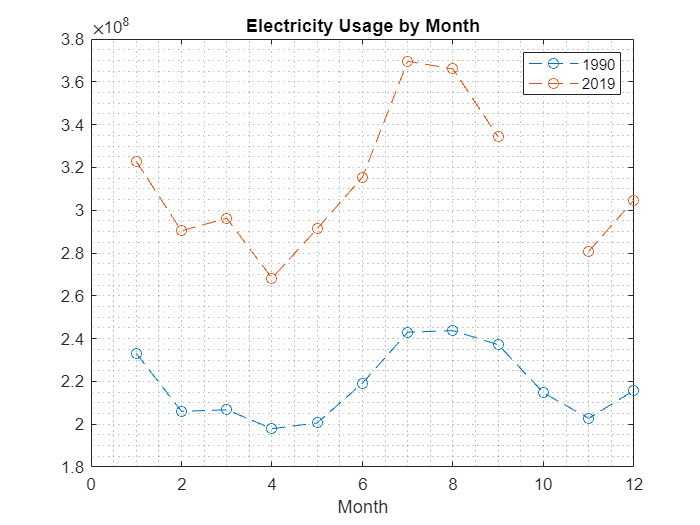

com = readmatrix("./data/electricity.xlsx", Sheet='com');
res = readmatrix("./data/electricity.xlsx", Sheet='res');
ind = readmatrix("./data/electricity.xlsx", Sheet='ind');

usage = ind + res + com;
firstYear = usage(:, 1);
lastYear = usage(:, end);

plot(1:12, firstYear, "o--")
hold on
plot(1:12, lastYear, "o--")
hold off
title("Electricity Usage by Month")
grid minor
legend("1990", "2019")
xlabel("Month")

usageDiff = lastYear - firstYear;

## Task 1

You can see in the plot that the electricity usage is higher in 2019 than 1990 for every month.  The starter code calculates the difference between the electricity data from 2019 and 1990 and saves it in the variable `usageDiff`.  Which month saw the highest change in electricity usage?

You can use the max function to calculate the largest element of a vector and the index where it occurs by requesting two outputs.

`[``m``,``idx``]` `=` `max``(``v``)``;`

[maxUsage, monthNum] = max(usageDiff)

maxUsage = 126627176

monthNum = 7

## Task 2

The maximum difference occurred in the seventh month, July.  To plot the usage for July over the years, extract the seventh row of `usage`.

To extract data from a matrix, specify the rows and columns you want.

`M``(``rows``,``cols``)`

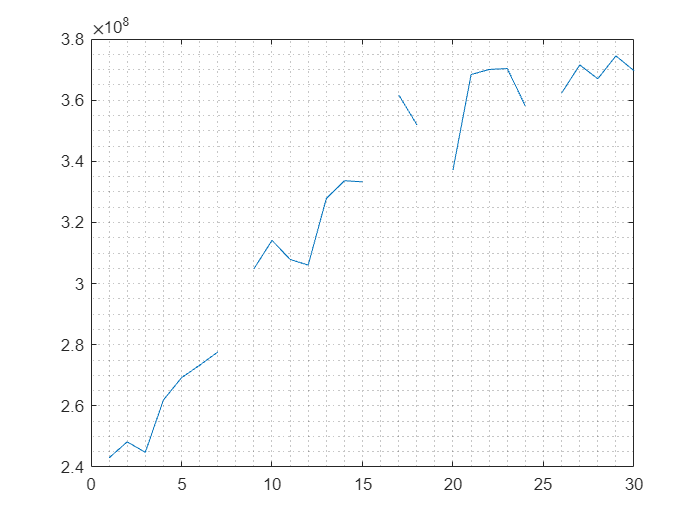

july = usage(monthNum, :);
plot(july)
grid minor

## Task 3

It may not surprise you that the largest increase of electricity usage was in summer.  Maybe more households have air conditioners or the average temperature is rising.  What are the other months with the largest change in electricity usage?

You can sort data from largest to smallest using `"descend"` option for the `sort` function.

`[``xSorted``,``idx``]` `=` `sort``(``v``,``"descend"``)`

`xSorted` is the vector, `v`, sorted from largest to smallest.  `idx` contains the corresponding indices of these values.

[diffSorted, sortedIdx] = sort(usageDiff, "descend")

diffSorted =          NaN
   126627176
   122266543
    97059873
    96292724
    90776351
    89723109
    89504278
    88955616
    84351022


sortedIdx =     10
     7
     8
     9
     6
     5
     1
     3
    12
     2
